clc; clearvars;

site = 'nybg';

% tempo
tempo_file = dir(['.\validation\time_series_data\tempo_',site,'.mat']);
tempo = load(fullfile(tempo_file.folder,tempo_file.name));

% tropomi
tropomi_file = dir(['.\validation\time_series_data\tropomi_',site,'.mat']);
tropomi = load(fullfile(tropomi_file.folder,tropomi_file.name));

% pandora
pandora_file = dir(['.\validation\time_series_data\',site,'_pandora_data.mat']);
pandora = load(fullfile(pandora_file.folder,pandora_file.name));

% merged
merged_file = dir(['.\validation\time_series_data\merged_',site,'.mat']);
merged = load(fullfile(merged_file.folder,merged_file.name));

## Filter based on data quality

% TEMPO high quality filter
tempo_cld_frac_threshold = 0.15;
tempo_high_q_filter = rowfilter(["vertical_column_troposphere","main_data_quality_flag", "solar_zenith_angle", "viewing_zenith_angle", "eff_cloud_fraction"]);
tempo_high_q_filter = (tempo_high_q_filter.vertical_column_troposphere>=0 & (tempo_high_q_filter.main_data_quality_flag==0 | tempo_high_q_filter.main_data_quality_flag==1) & tempo_high_q_filter.solar_zenith_angle<70 & tempo_high_q_filter.viewing_zenith_angle<70 & tempo_high_q_filter.eff_cloud_fraction<tempo_cld_frac_threshold);

% TROPOMI high quality filter
tropomi_qa_threshold = 0.75;
tropomi_high_q_filter = rowfilter("qa_value");
tropomi_high_q_filter = tropomi_high_q_filter.qa_value>=tropomi_qa_threshold;

% Pandora high quality filter
include_unassured = true;
pandora_quality = "high";
pandora_high_q_filter = rowfilter("qa");
if include_unassured == true
    if pandora_quality == "high"
        pandora_high_q_filter = (pandora_high_q_filter.qa == 0 | pandora_high_q_filter.qa == 10);
    elseif pandora_quality == "medium"
        pandora_high_q_filter = (pandora_high_q_filter.qa == 0 | pandora_high_q_filter.qa == 1 | pandora_high_q_filter.qa == 10 | pandora_high_q_filter.qa == 11);
    elseif pandora_quality == "low"
        pandora_high_q_filter = (pandora_high_q_filter.qa == 0 | pandora_high_q_filter.qa == 1 | pandora_high_q_filter.qa == 2 | pandora_high_q_filter.qa == 10 | pandora_high_q_filter.qa == 11| pandora_high_q_filter.qa == 12);
    end
elseif include_unassured == false
    if pandora_quality == "high"
        pandora_high_q_filter = pandora_high_q_filter.qa == 0;
    elseif pandora_quality == "medium"
        pandora_high_q_filter = (pandora_high_q_filter.qa == 0 | pandora_high_q_filter.qa == 1);
    elseif pandora_quality == "low"
        pandora_high_q_filter = (pandora_high_q_filter.qa == 0 | pandora_high_q_filter.qa == 1 | pandora_high_q_filter.qa == 2);
    end
end
% Apply filters to tables
tempo_high_q = tempo.data_table(tempo_high_q_filter,:);
tropomi_high_q = tropomi.data_table(tropomi_high_q_filter,:);
pandora_high_q = pandora.pandora_data(pandora_high_q_filter,:);

% convert tables to timetables
tempo_high_q = tempo_table2timetable(tempo_high_q);
tropomi_high_q = tropomi_table2timetable(tropomi_high_q);
pandora_high_q = table2timetable(pandora_high_q);

% Change units in tempo tables
tempo_high_q = convert_tempo_units(tempo_high_q);

## Plot data over time

need to add groun monitor data

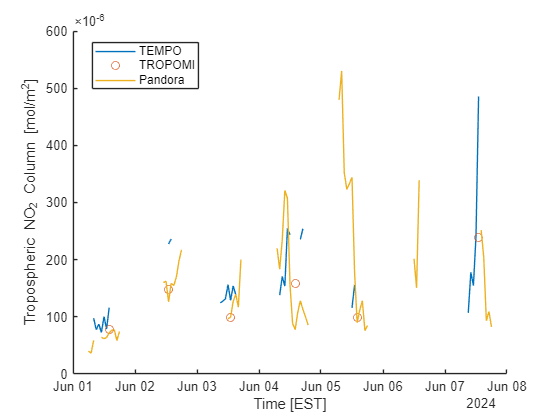

binning = "hourly";
start_day = datetime("2024-06-01", "InputFormat", "uuuu-MM-dd"); start_hour =0;
end_day =   datetime("2024-06-08", "InputFormat", "uuuu-MM-dd"); end_hour =0;
start_day.TimeZone = 'America/New_York';
end_day.TimeZone = 'America/New_York';

if binning == "hourly"
    retime_bins = "hourly";
elseif binning == "daily"
    retime_bins = "daily";
elseif binning == "weekly"
    retime_bins = "weekly";
elseif binning == "monthly"
    retime_bins = "monthly";
end


if binning == "none"
    plot_tempo_high_q = tempo_high_q;
    plot_tropomi_high_q = tropomi_high_q;
    plot_pandora_high_q = pandora_high_q;
else
    plot_tempo_high_q = retime(tempo_high_q, retime_bins, "mean");
    plot_tropomi_high_q = retime(tropomi_high_q, retime_bins, "mean");
    plot_pandora_high_q = retime(pandora_high_q, retime_bins, "mean");
end

figure;
hold on;
plot(plot_tempo_high_q.time, plot_tempo_high_q.vertical_column_troposphere);
scatter(plot_tropomi_high_q.time, plot_tropomi_high_q.nitrogendioxide_tropospheric_column);
plot(plot_pandora_high_q.Date, plot_pandora_high_q.NO2);
xlabel('Time [EST]')
ylabel('Tropospheric NO_{2} Column [mol/m^2]')

hold off
xlim([start_day+hours(start_hour), end_day+hours(end_hour)])
legend(["TEMPO", "TROPOMI", "Pandora"], "Location","best")
ax = gca;
ax.XAxis.ReferenceDate = datetime(2020,01,01, "TimeZone","America/New_York");
ax.YAxis.Exponent = -6;

Find pandora measurements closest to satellite measurements at each site

average satellite measurements with 5 minute bin to average retrievals in the same granule

get pandora measurements within 30 minutes to the satellite bin

bin = minutes(5);
binned_tempo_high_q = retime(tempo_high_q, 'regular', 'mean', 'TimeStep', bin); binned_tempo_high_q = rmmissing(binned_tempo_high_q);
binned_tropomi_high_q = retime(tropomi_high_q, 'regular', 'mean', 'TimeStep', bin); binned_tropomi_high_q = rmmissing(binned_tropomi_high_q);
binned_pandora_high_q = retime(pandora_high_q, 'regular', 'mean', 'TimeStep', bin); binned_pandora_high_q = rmmissing(binned_pandora_high_q);

n_tempo = size(binned_tempo_high_q,1);
n_tropomi = size(binned_tropomi_high_q,1);
n_pandora = size(binned_pandora_high_q,1);

correlation_threshold = minutes(10);

tempo_pandora = NaN(n_tempo,1);
for i = 1:n_tempo
    temp_pandora = binned_pandora_high_q(abs(binned_pandora_high_q.Date - binned_tempo_high_q.time(i)) <= correlation_threshold, :);
    tempo_pandora(i) = mean(temp_pandora.NO2, 'all', 'omitmissing');
end
binned_tempo_high_q.PANDORA_NO2 = tempo_pandora;
binned_tempo_high_q = rmmissing(binned_tempo_high_q);

tropomi_pandora = NaN(n_tropomi,1);
for i = 1:n_tropomi
    temp_pandora = binned_pandora_high_q(abs(binned_pandora_high_q.Date - binned_tropomi_high_q.time(i)) <= correlation_threshold, :);
    tropomi_pandora(i) = mean(temp_pandora.NO2, 'all', 'omitmissing');
end
binned_tropomi_high_q.PANDORA_NO2 = tropomi_pandora;
binned_tropomi_high_q = rmmissing(binned_tropomi_high_q);

## Linear Correlation

tempo_p = polyfit(binned_tempo_high_q.PANDORA_NO2, binned_tempo_high_q.vertical_column_troposphere, 1);
tropomi_p = polyfit(binned_tropomi_high_q.PANDORA_NO2, binned_tropomi_high_q.nitrogendioxide_tropospheric_column, 1);

tempo_fit = polyval(tempo_p, binned_tempo_high_q.PANDORA_NO2);
tropomi_fit = polyval(tropomi_p, binned_tropomi_high_q.PANDORA_NO2);

% correlation coefficient
tempo_corr = corrcoef(binned_tempo_high_q.PANDORA_NO2, binned_tempo_high_q.vertical_column_troposphere);
tropomi_corr = corrcoef(binned_tropomi_high_q.PANDORA_NO2, binned_tropomi_high_q.nitrogendioxide_tropospheric_column);

% r squared
tempo_Rsq = 1 - sum((binned_tempo_high_q.vertical_column_troposphere - tempo_fit).^2)/sum((binned_tempo_high_q.vertical_column_troposphere - mean(binned_tempo_high_q.vertical_column_troposphere)).^2);
tropomi_Rsq = 1 - sum(( binned_tropomi_high_q.nitrogendioxide_tropospheric_column - tropomi_fit).^2)/sum(( binned_tropomi_high_q.nitrogendioxide_tropospheric_column - mean(binned_tropomi_high_q.nitrogendioxide_tropospheric_column)).^2);

## Plots

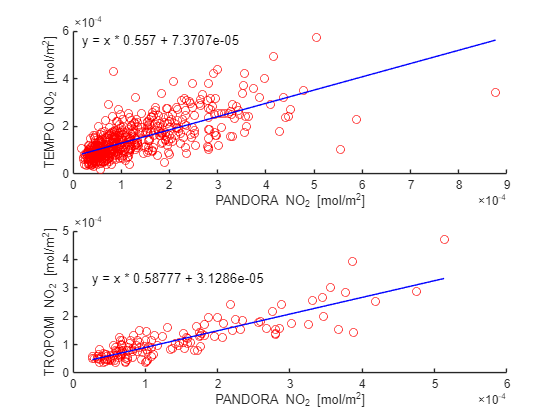

figure;
subplot(2,1,1)
hold on;
plot(binned_tempo_high_q.PANDORA_NO2, binned_tempo_high_q.vertical_column_troposphere, 'ro')
plot(binned_tempo_high_q.PANDORA_NO2, tempo_fit, 'b')
hold off,
text(min(binned_tempo_high_q.PANDORA_NO2), max(tempo_fit), ['y = x * ',num2str(tempo_p(1)), ' + ', num2str(tempo_p(2))])
xlabel('PANDORA NO_{2} [mol/m^2]')
ylabel('TEMPO NO_{2} [mol/m^2]')

subplot(2,1,2)
hold on;
plot(binned_tropomi_high_q.PANDORA_NO2, binned_tropomi_high_q.nitrogendioxide_tropospheric_column, 'ro')
plot(binned_tropomi_high_q.PANDORA_NO2, tropomi_fit, 'b')
hold off;
text(min(binned_tropomi_high_q.PANDORA_NO2), max(tropomi_fit), ['y = x * ',num2str(tropomi_p(1)), ' + ', num2str(tropomi_p(2))])
xlabel('PANDORA NO_{2} [mol/m^2]')
ylabel('TROPOMI NO_{2} [mol/m^2]')

function table_out = tempo_table2timetable(table_in)
    table_out = table_in;
    table_out.time = datetime(table_out.time, 'ConvertFrom', 'epochtime', 'Epoch', '1980-01-06', 'TimeZone', 'UTC');
    table_out = table2timetable(table_out);
    % table_out.time.TimeZone = 'UTC';
    table_out = sortrows(table_out, "time");
end

function table_out = tropomi_table2timetable(table_in)
    table_out = table_in;
    day_temp = datetime(table_out.time, "ConvertFrom", "epochtime", "Epoch",'2010-01-01', 'TimeZone', 'UTC');
    tropomi_times = NaT(size(day_temp), "TimeZone","UTC");

    for i = 1:length(tropomi_times)
        tropomi_times(i) = datetime(table_out.delta_time(i), "ConvertFrom", "epochtime","Epoch", day_temp(i) ,"TicksPerSecond",1000, "TimeZone","UTC");
    end

    table_out = removevars(table_out, "delta_time");
    table_out.time = tropomi_times;
    table_out = table2timetable(table_out);
    % table_out.time.TimeZone = 'UTC';
    table_out = sortrows(table_out, "time");
end

function table_out = convert_tempo_units(table_in)
    table_out = table_in;
    table_out.vertical_column_troposphere = table_out.vertical_column_troposphere ./ conversion_factor('trop-tempo');
    table_out.vertical_column_troposphere_uncertainty = table_out.vertical_column_troposphere_uncertainty ./ conversion_factor('trop-tempo');
end